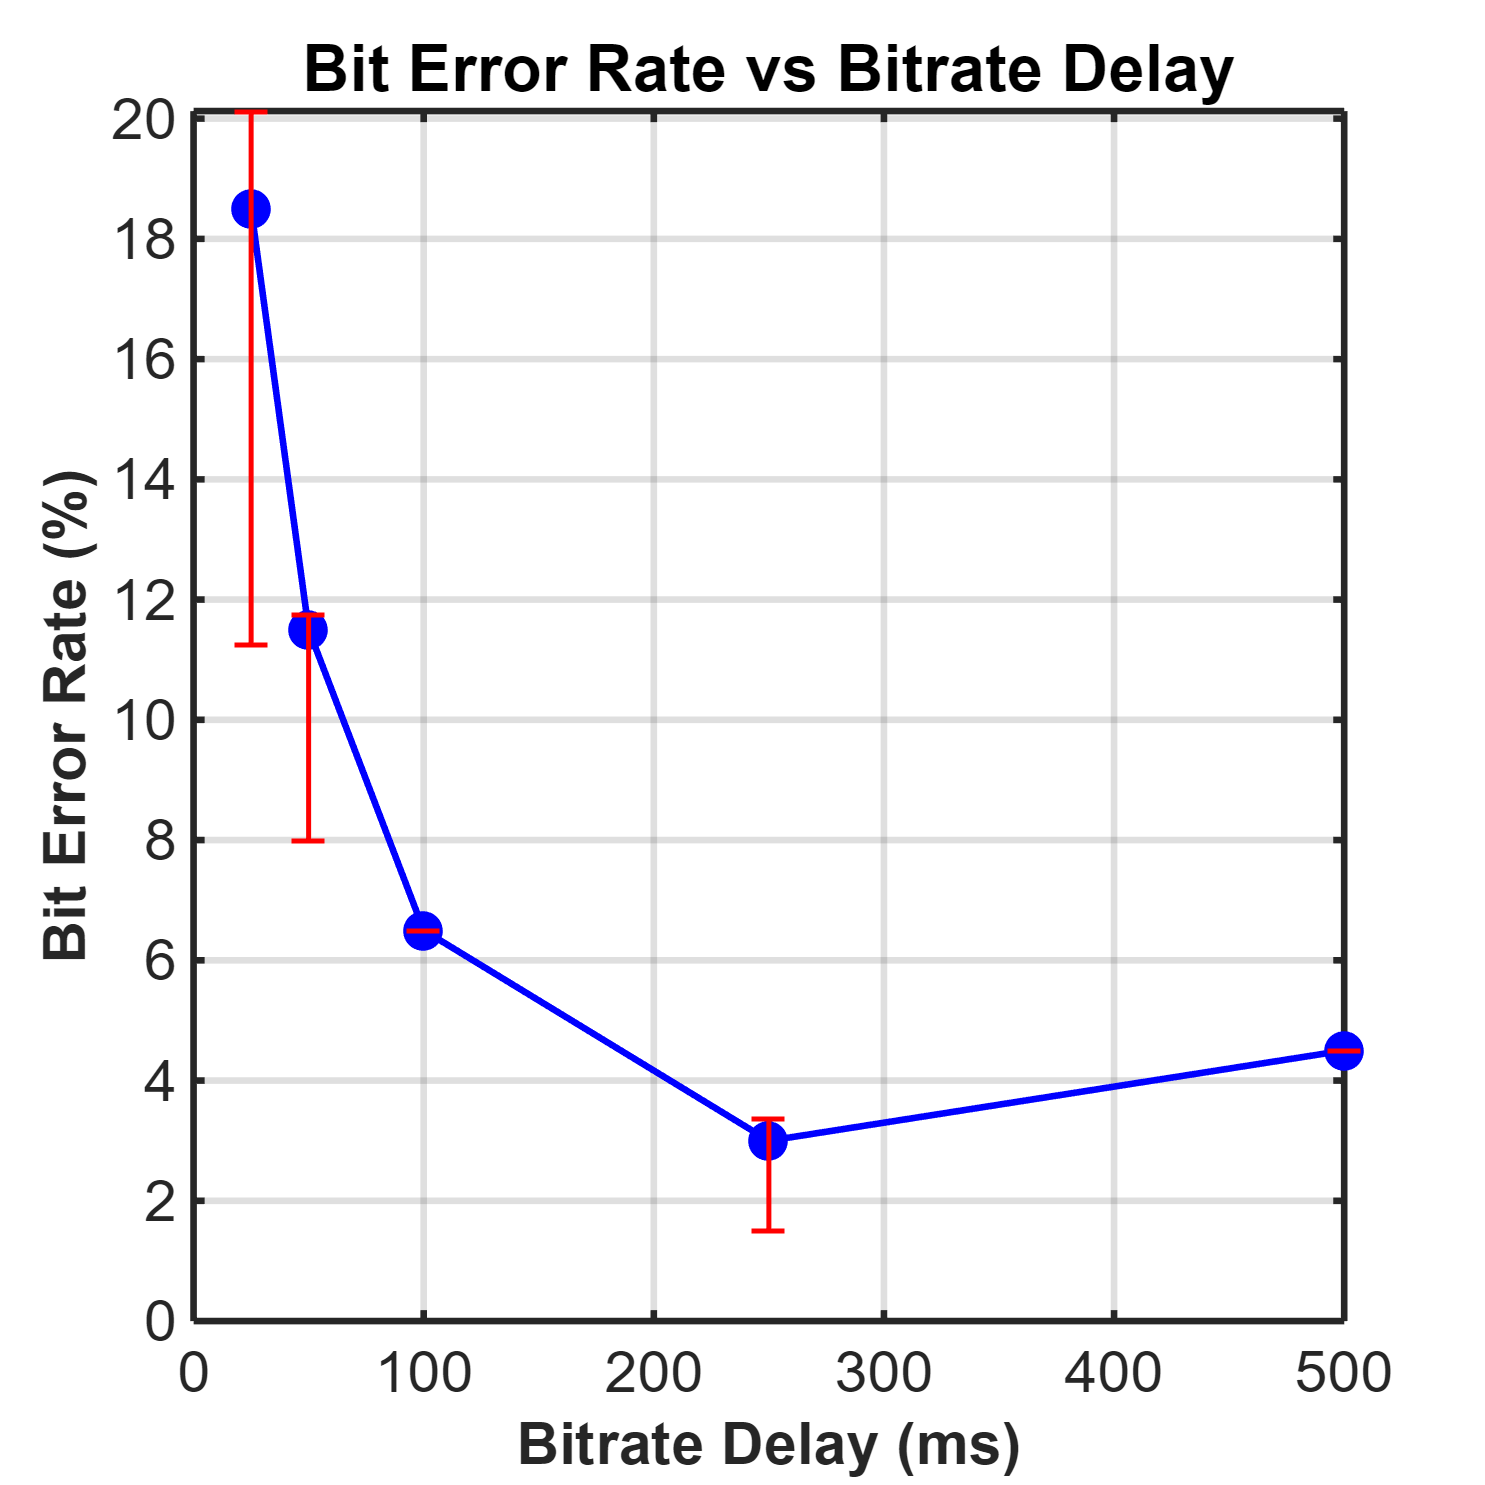

%{
EXPERIMENTAL DATA

Back of tank, volume at 50cm
VOL = 1/16, recv = 54, 98, 105
VOL = 2/16, recv = 201, 210, 195 (buzz)
VOL = 5/16, recv = 210, 211, 174
VOL = 8/16, recv = 211, 210, 210
VOL = 12/16, recv = 196, 210, 210
VOL = 16/16, recv = 210, 211, 210

DIST
(got)

BITRATE
Delay = 10ms (not reliable)
Dist = 50cm
Sound = max
25ms: 203, 229, 237, 241, 240
50ms: 224, 191, 223, 223
100ms: 213, 213, 213
250ms: 198, 207, 206
500ms: 191

%}


%% Bitrate vs Bit Error Rate (blue data, red error bars)
figure;
hold on;
% Plot main data line and markers (blue)
plot(bitrate_delays, ber_median * 100, 'o-', 'Color', 'b', 'LineWidth', 2);

% Plot error bars separately in red
for i = 1:length(bitrate_delays)
    x = bitrate_delays(i);
    y = ber_median(i) * 100;
    yneg = (ber_median(i) - ber_25(i)) * 100;
    ypos = (ber_75(i) - ber_median(i)) * 100;
    eb = errorbar(x, y, yneg, ypos, 'o', 'Color', 'g', 'LineWidth', 1.5, ...
                  'Marker', 'none', 'CapSize', 10);
end

xlabel('Bitrate Delay (ms)');
ylabel('Bit Error Rate (%)');
title('Bit Error Rate vs Bitrate Delay');
grid on;
improvePlot;

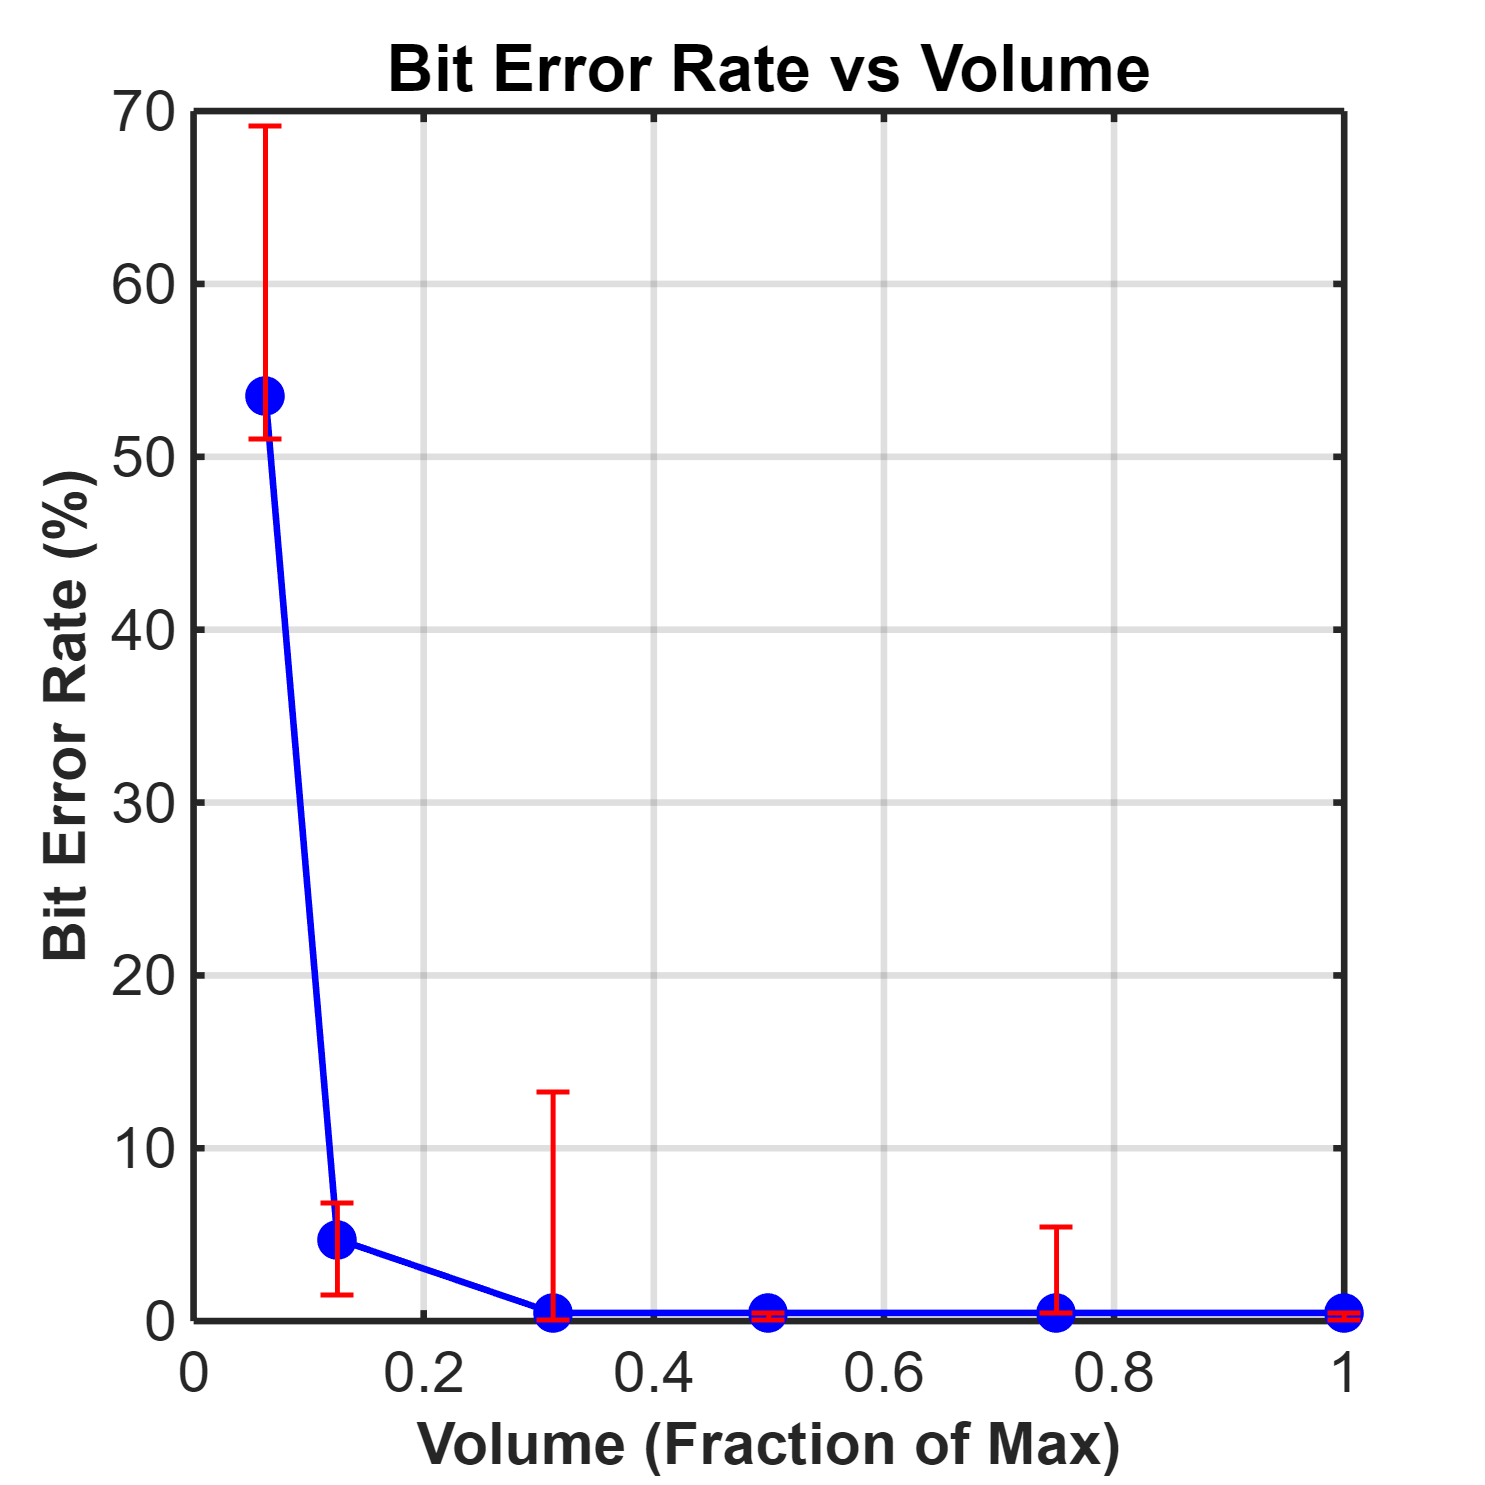


%% Volume vs Bit Error Rate (blue data, red error bars)
figure;
hold on;
% Plot main data line and markers (blue)
plot(volume_frac, ber_median_v * 100, 'o-', 'Color', 'b', 'LineWidth', 2);

% Plot error bars separately in red
for i = 1:length(volume_frac)
    x = volume_frac(i);
    y = ber_median_v(i) * 100;
    yneg = (ber_median_v(i) - ber_25_v(i)) * 100;
    ypos = (ber_75_v(i) - ber_median_v(i)) * 100;
    eb = errorbar(x, y, yneg, ypos, 'o', 'Color', 'r', 'LineWidth', 1.5, ...
                  'Marker', 'none', 'CapSize', 10);
end

xlabel('Volume (Fraction of Max)');
ylabel('Bit Error Rate (%)');
title('Bit Error Rate vs Volume');
grid on;
improvePlot;

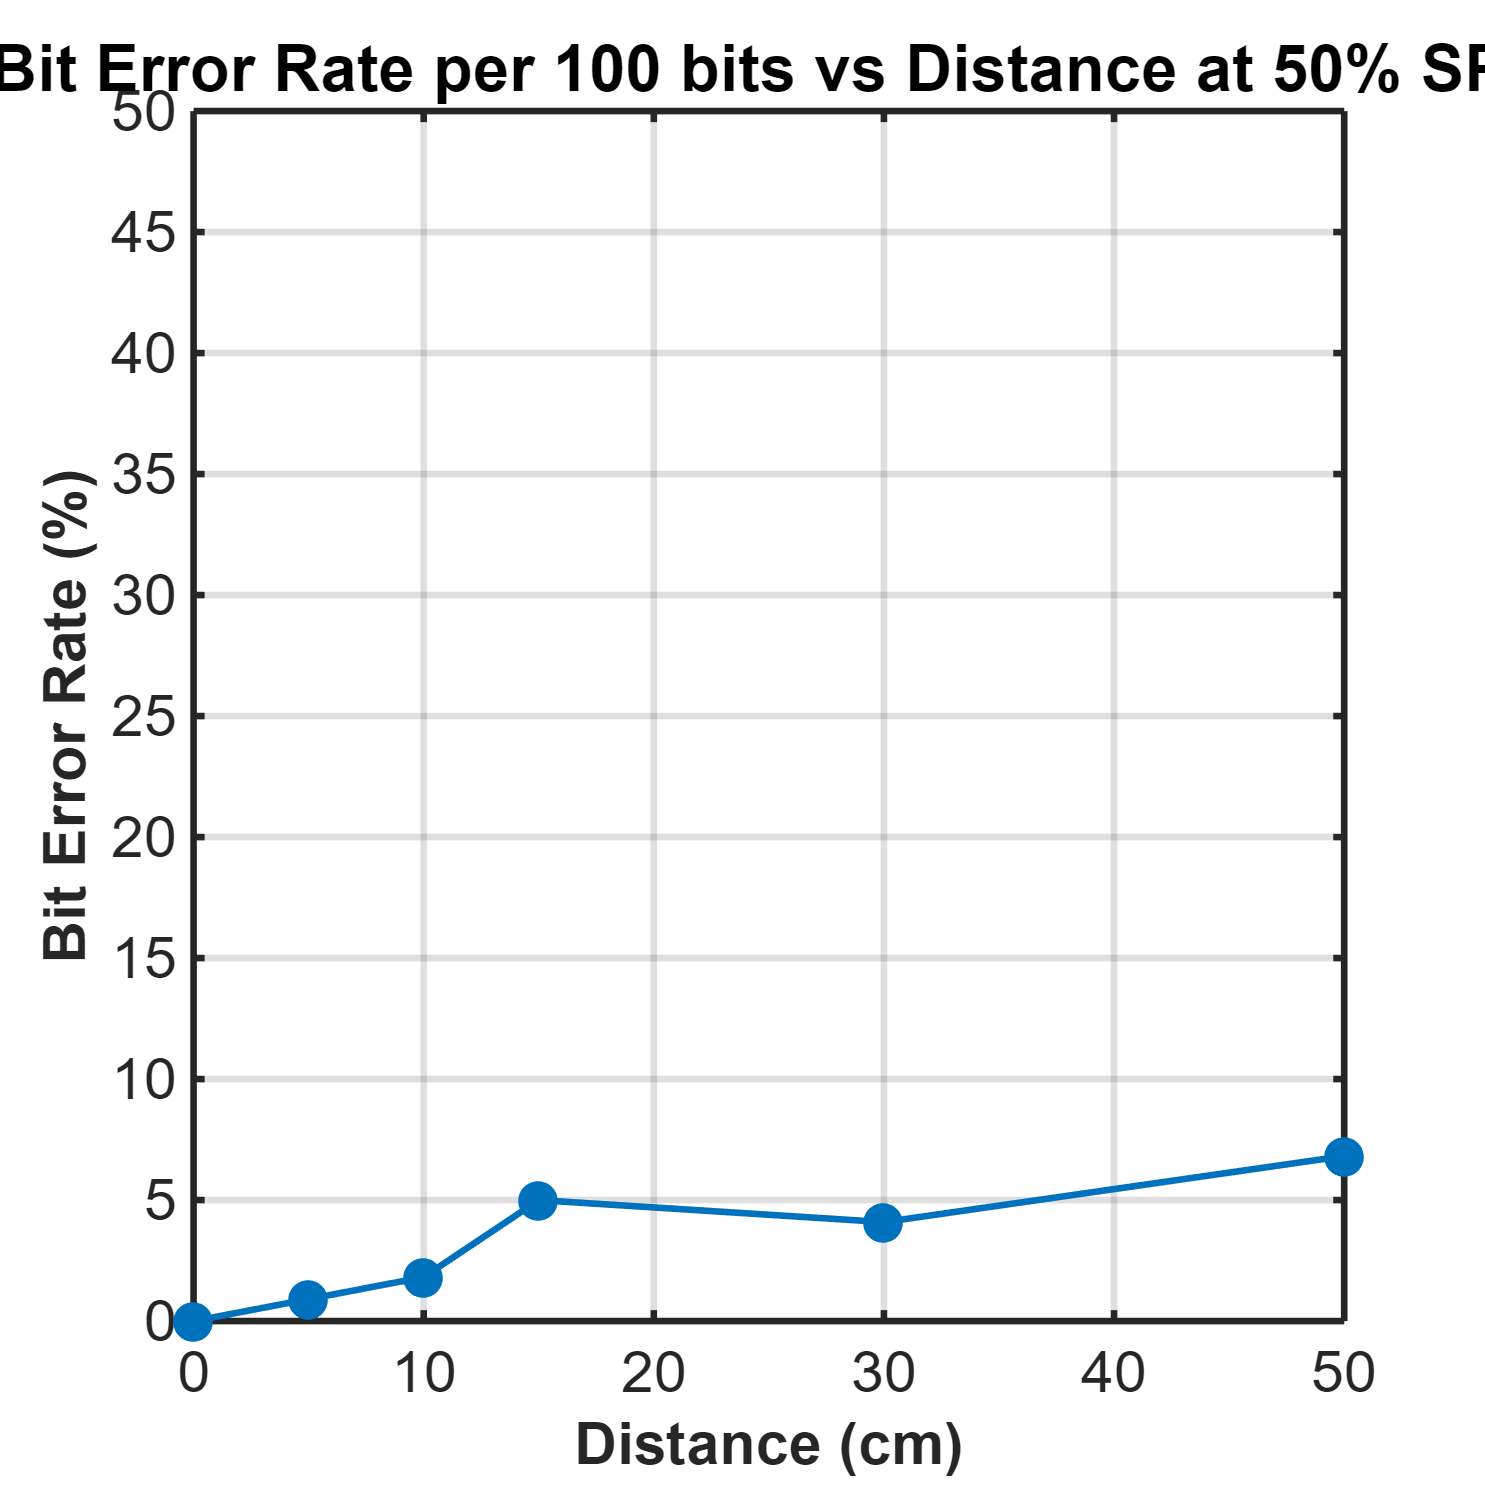



% Data for Plot 1: Speaker to Hydrophone
% Given bit error rate data from Plot 1
distance1 = [0, 5, 10, 15, 30, 50];
received_count = [220, 218, 216, 209, 211, 205];
bit_error_rate = abs((received_count./received_count(1)) - 1); % Convert % to fraction

% Plot 1
figure;
plot(distance1, bit_error_rate*100, 'o-', 'LineWidth', 2);
xlabel('Distance (cm)');
ylabel('Bit Error Rate (%)');
title('Bit Error Rate per 100 bits vs Distance at 50% SPL');
grid on;
ylim([0 50])
improvePlot;

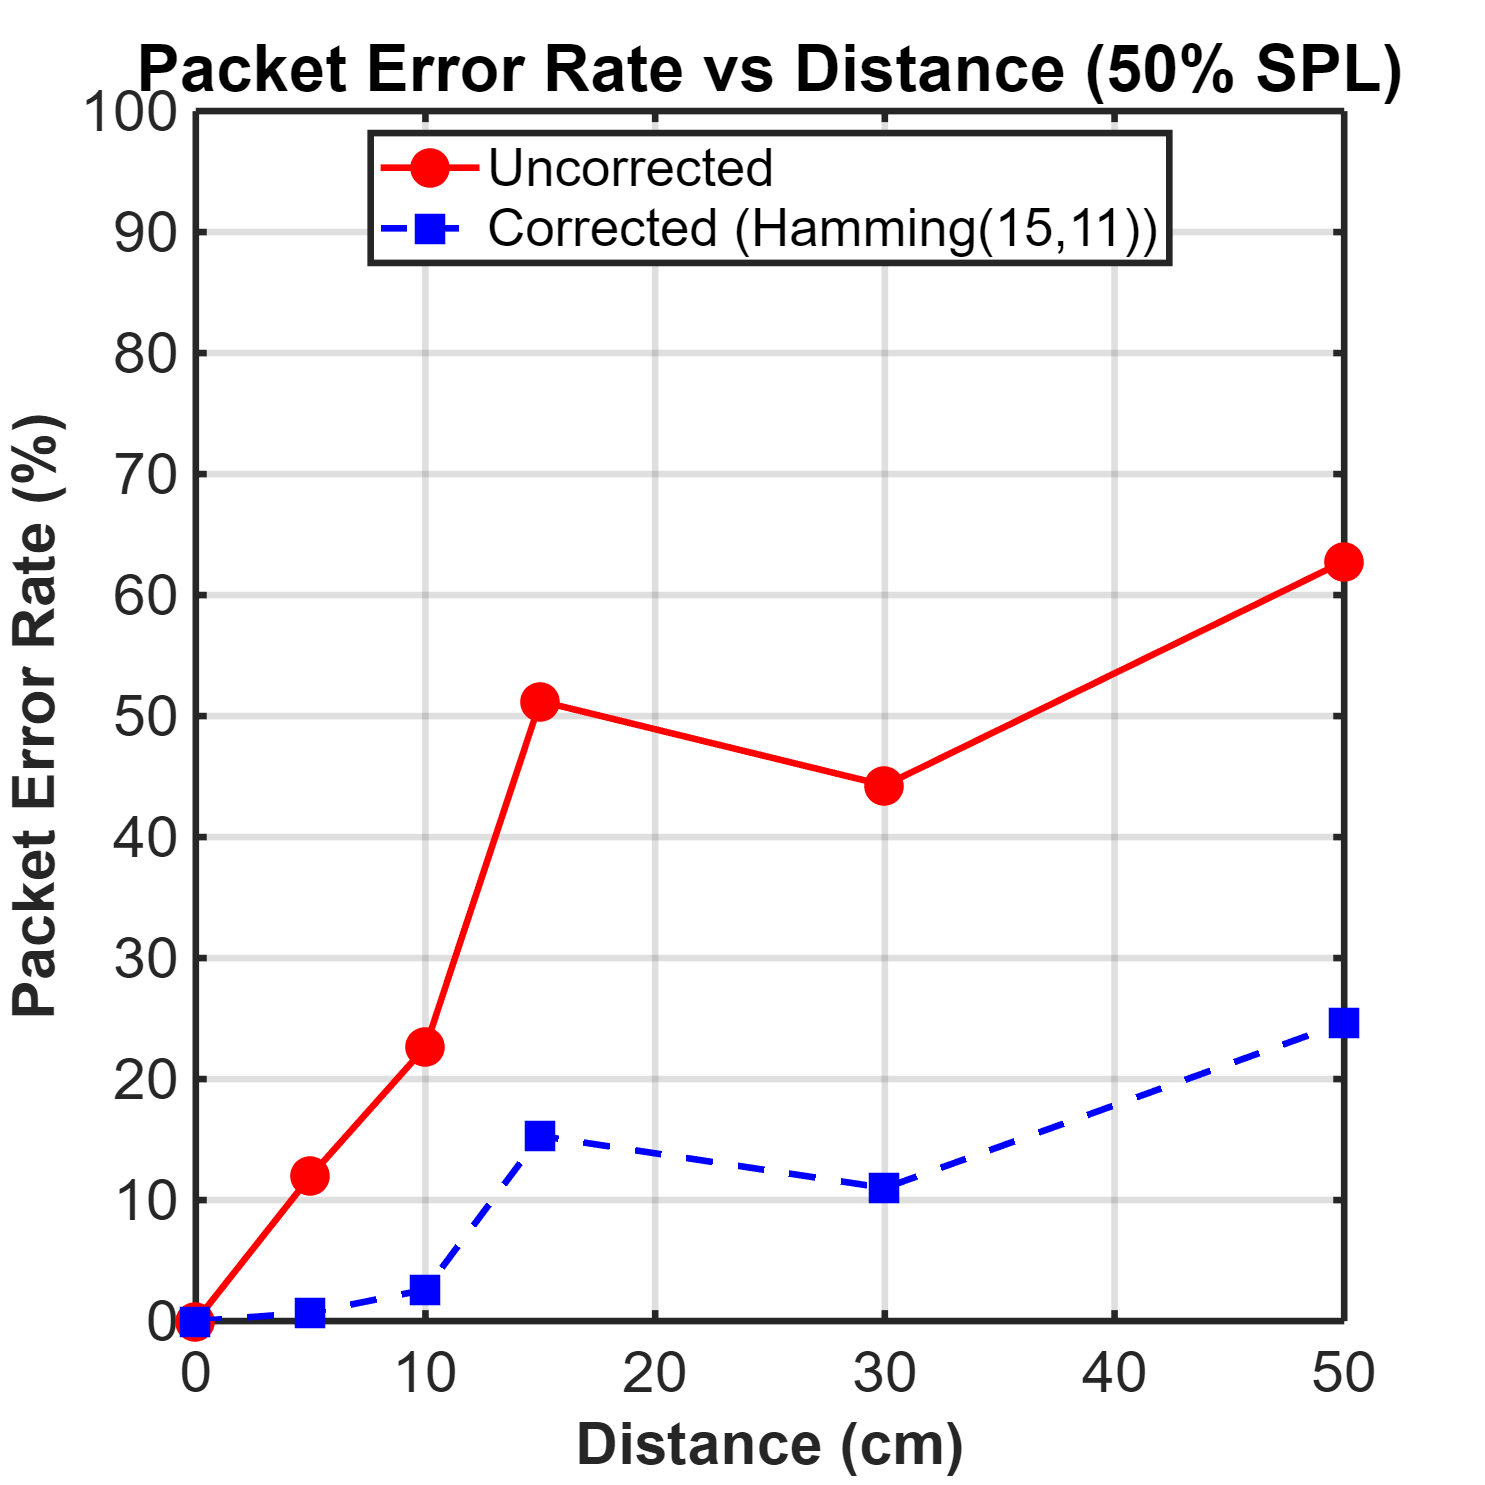


% 270 at dist=0
% 216 at dist=5
% 218 at dist=10
% 209 at dist=15
% 211 at dist=30
% 196 at dist=50


packet_len = 14;

% Uncorrected Packet Error Rate (PER): probability that >=1 bit is wrong
per_uncorrected = 1 - (1 - bit_error_rate).^packet_len;

% Corrected Packet Error Rate (1-bit correct, 2-bit detect)
% Assume packet fails if 2 or more bits are wrong.
% Use binomial approximation: PER = P(2 errors) + P(3 errors) + ...
per_corrected = zeros(size(bit_error_rate));
for i = 1:length(bit_error_rate)
    p = bit_error_rate(i);
    prob_0 = (1 - p)^packet_len;
    prob_1 = packet_len * p .* (1 - p).^(packet_len - 1);
    per_corrected(i) = 1 - (prob_0 + prob_1); % only 0 and 1 bit errors succeed
end

% Plot corrected and uncorrected PERs
figure;
hold on;
plot(distance1, per_uncorrected * 100, 'ro-', 'LineWidth', 2, 'DisplayName', 'Uncorrected');
plot(distance1, per_corrected * 100, 'bs--', 'LineWidth', 2, 'DisplayName', 'Corrected (Hamming(15,11))');
xlabel('Distance (cm)');
ylabel('Packet Error Rate (%)');
title('Packet Error Rate vs Distance (50% SPL)');
legend('Location','northwest');
grid on;
ylim([0 100])
improvePlot;

function [] = improvePlot()
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Plot parameters
    % MATLAB treats mac and PC displays differently which can create
    % weird looking graphs. Here we handle system differences

    if ismac
        plot_width_in_px = 800;
        plot_height_in_px = 800;
        marker_size=15;
        marker_line_width=2.5;
        box_thickness = 3;
        axis_tick_font_size = 24;
        axis_label_font_size = 24;
        legend_font_size = 20;
        error_bar_cap_size = 15;
    else % (ispc || isunix)
        plot_width_in_px = 600;
        plot_height_in_px = 600;
        marker_size=10;
        marker_line_width=2.0;
        box_thickness = 2;
        axis_tick_font_size = 18;
        axis_label_font_size = 18;
        legend_font_size = 16;
        error_bar_cap_size = 10;
    end
    
    marker_outline = 'matching'; % could be 'black' or 'matching'

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    % Use h as handle for current figure
    hFig = gcf;                    
    % Change figure background colour to white
    set(hFig, 'Color', 'white');

    % Make the figure bigger
    set(hFig, 'rend', 'painters', 'Units', 'pixels', 'pos', ...
        [100 100 plot_width_in_px plot_height_in_px]);

    % Grab the axes handle(s)
    axis_handles=findobj(hFig,'type','axe');

    % Iterate over all axes handle(s), this is useful if there are subplots
    for i = 1:length(axis_handles)
        ax = axis_handles(i);

        % Change default font size (tick labels, legend, etc.)
        set(ax, 'FontSize', axis_tick_font_size, 'FontName', 'Arial', 'LineWidth', box_thickness);
        
        set(ax, 'Box', 'on');

        % Change font size for axis text labels
        set(get(ax, 'XLabel'),'FontSize', axis_label_font_size, 'FontWeight', 'Bold');
        set(get(ax, 'YLabel'),'FontSize', axis_label_font_size, 'FontWeight', 'Bold');
        
        try % try statement to avoid error with categorical axes
        ax.XRuler.Exponent = 0; % Remove exponential notation from the X axis
        ax.YRuler.Exponent = 0; % Remove exponential notation from the Y axis
        catch
        end
        
    end
    
    % Find all the lines, and markers
    LineH = findobj(hFig, 'type', 'line', '-or', 'type', 'errorbar');

    if(~isempty(LineH))
        for i=1:length(LineH) % Iterate over all lines in the plot
            % Decide what color for the marker edges
            this_line_color = get(LineH(i),'color');
            if strcmp(marker_outline, 'black')
                marker_outline_color = 'black';
            elseif strcmp(marker_outline, 'matching')
                marker_outline_color = this_line_color;
            else
                marker_outline_color = 'black';
            end

            % If the LineWidth has not been customized, then change it
            if (get(LineH(i), 'LineWidth') <= 1.0)
                set(LineH(i), 'LineWidth', marker_line_width)
            end
            % Change lines and markers if they exist on the plot
            set(LineH(i),   'MarkerSize', marker_size, ...
                'MarkerEdgeColor', marker_outline_color, ...
                'MarkerFaceColor', this_line_color);
        end
    end

    % Find and change the error bars
    LineH = findobj(hFig, 'type', 'errorbar');
    if(~isempty(LineH))
        for i=1:length(LineH) % Iterate over all lines in the plot
            LineH(i).CapSize=error_bar_cap_size;
%             LineH(i).Color = [0 0 0]; % Set all error bars to black

        end
    end

    % Find the legend, and if there is one, change it  
    h = get(hFig,'children');
    for k = 1:length(h)
        if strcmpi(get(h(k),'Tag'),'legend')
            set(h(k), 'FontSize', legend_font_size, 'location', 'best');
            break;
        end
    end

end